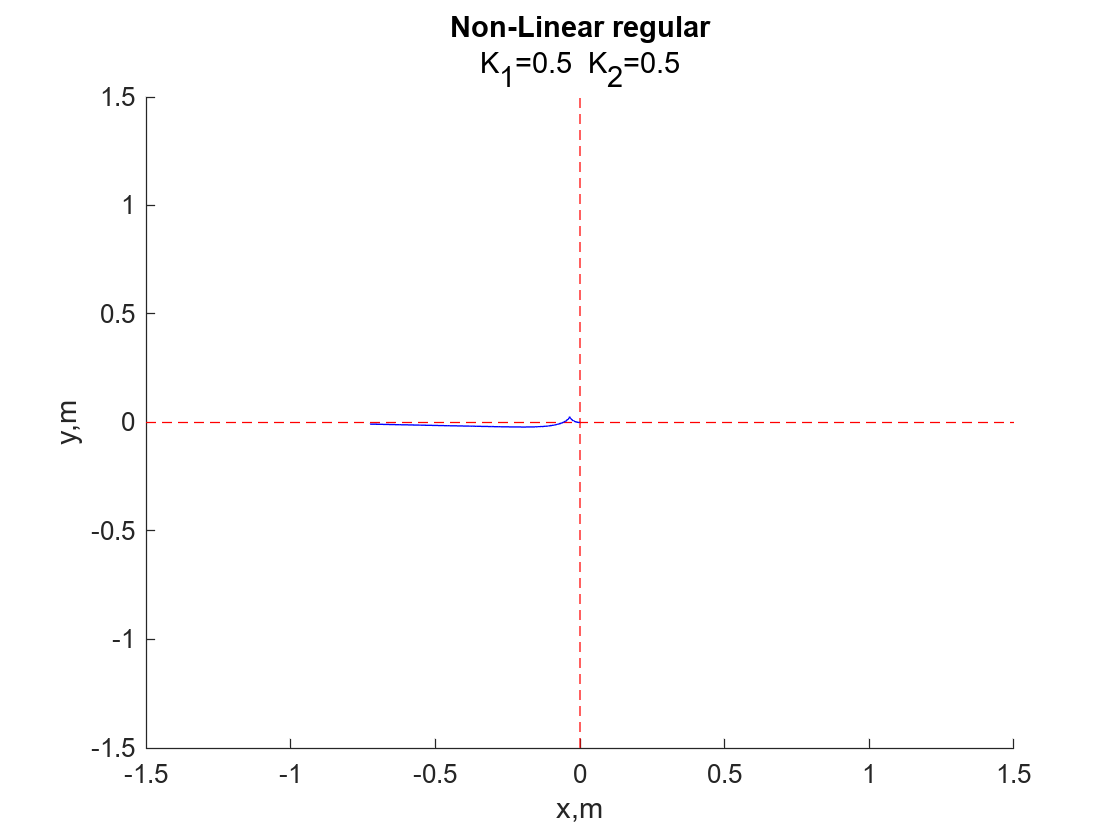

K1 = 0.5000

K2 = 0.5000

simout =   Simulink.SimulationOutput:

                      V: [1x1 timeseries] 
                   tout: [28256x1 double] 
                      x: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


K1 = 1

K2 = 1

simout =   Simulink.SimulationOutput:

                      V: [1x1 timeseries] 
                   tout: [155x1 double] 
                      x: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


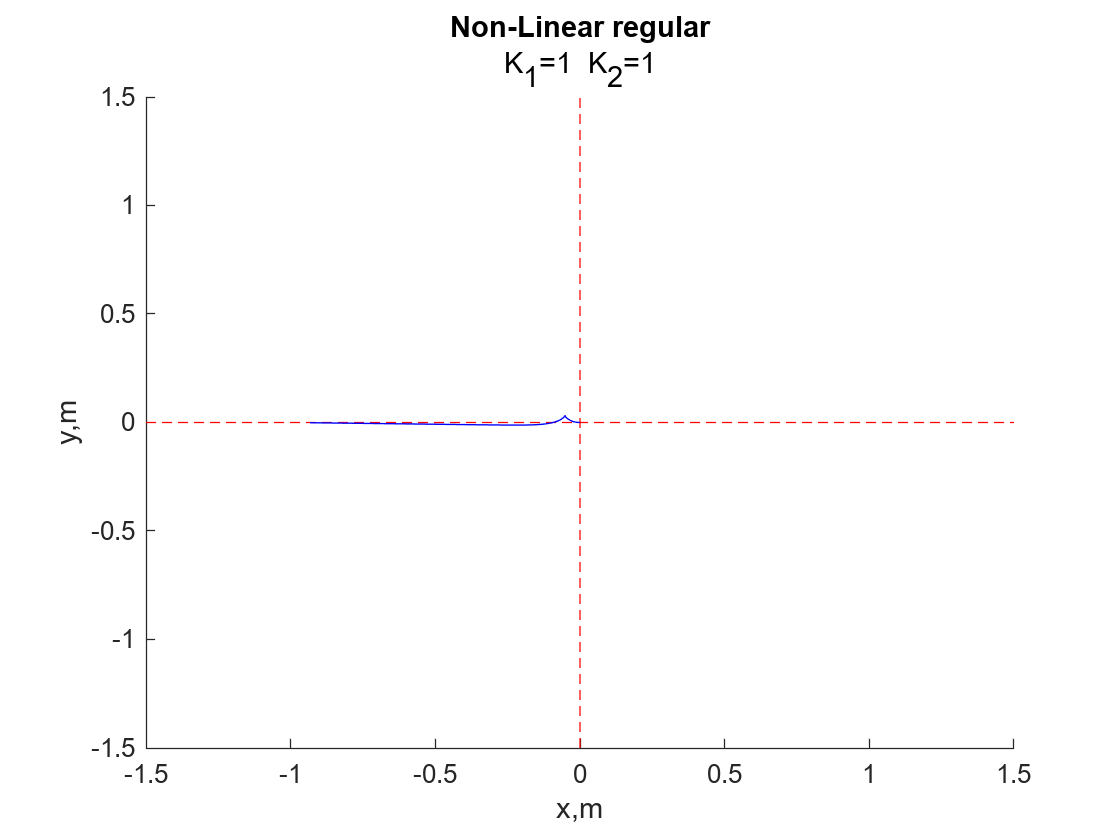

K1 = 5

K2 = 5

simout =   Simulink.SimulationOutput:

                      V: [1x1 timeseries] 
                   tout: [168x1 double] 
                      x: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


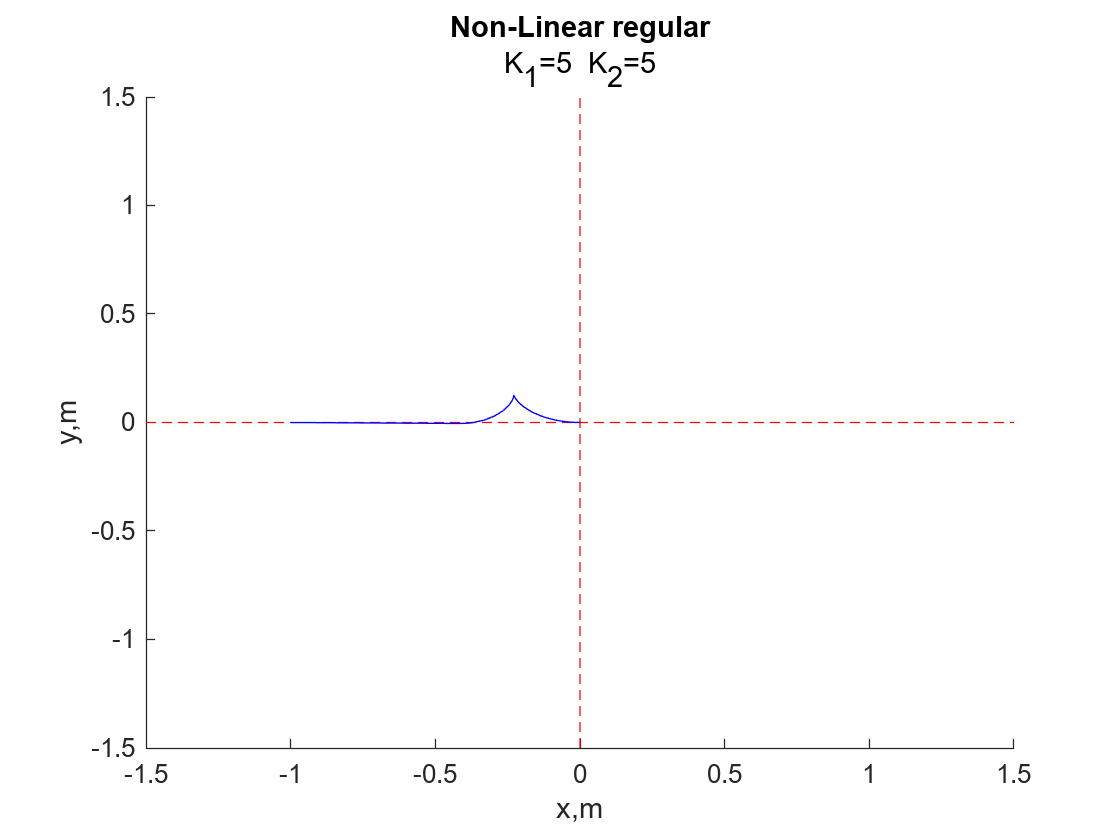

ke = 0.4987;
km = ke; 
R =  8.8696;
L = 0.0047;
J = 0.0023;
r=0.028;
B=0.21;
goal_x=-1;
goal_y=0;
start_x=0;
start_y=0;
h=1.5;
xlim([-h h])
ylim([-h h])
for i=[0.5 1 5]
    K1=i
    K2=i
    figure(i*100)
    simout=sim('VPD_lab_4_nonlinear.slx')
    hold on;
    plot([-h, h], [0, 0], 'r--')
    plot([0, 0], [-h, h], 'r--')
    plot(simout.x.Data, simout.y.Data,'b')
    hold off;
    h2 = strcat('K_1=',string(K1),'  K_2=', string(K2));
    title('Non-Linear regular',h2)
    xlabel('x,m');
    ylabel('y,m');
end

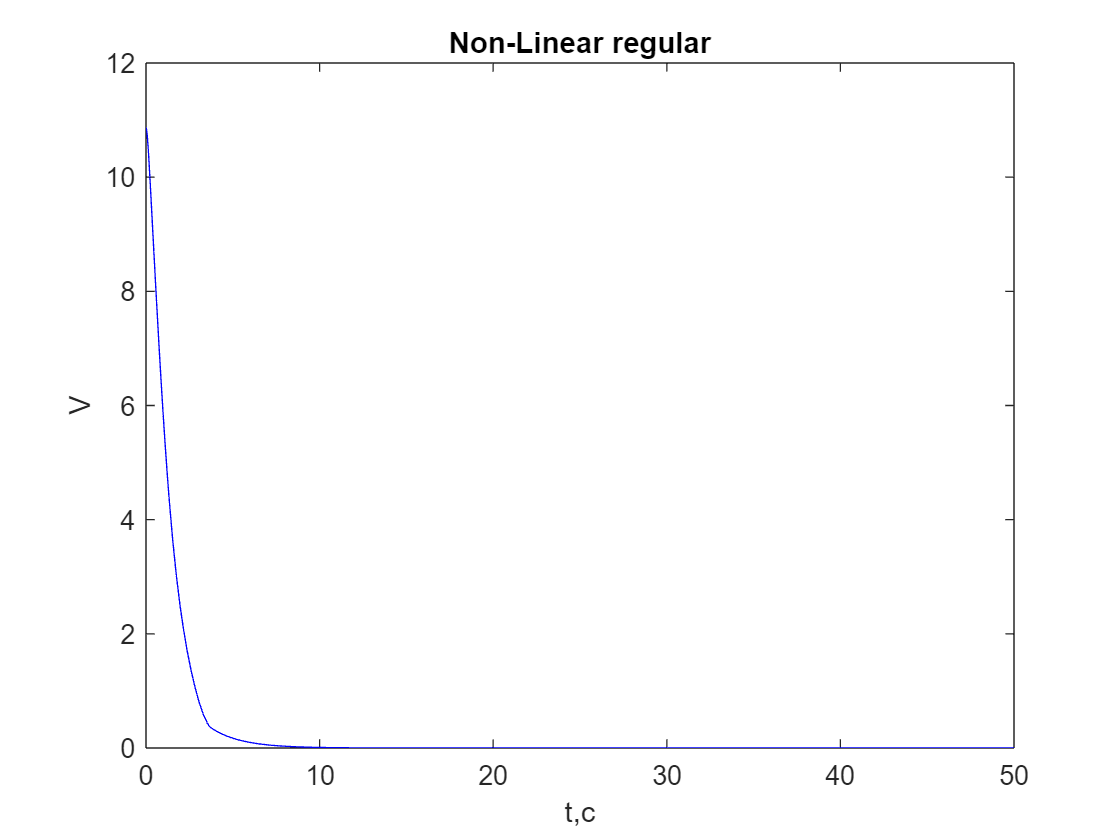

plot(simout.V.Time, simout.V.Data,'b')
xlabel('t,c');
ylabel('V');
title('Non-Linear regular')